# Logistic Regression

### Importing the data

% Load Data
% The first two columns contain the exam scores and the third column
% contains the label.
data = load('ex2data1.txt');
X = data(:, [1, 2]);
y = data(:, 3);

### Visualising the data

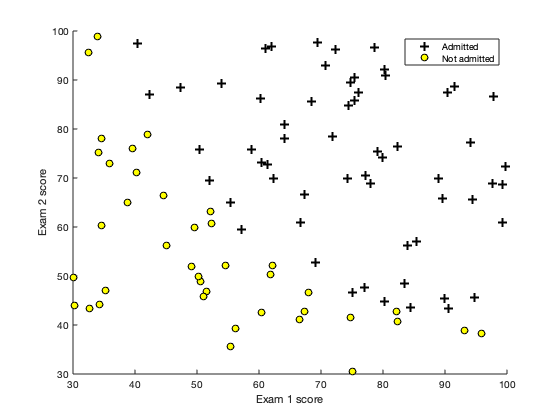

plotData(X,y);

% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')

% Specified in plot order
legend('Admitted', 'Not admitted')

### Testing the sigmoid function

sigmoid(0)

ans = 0.5000

### Cost function and gradient

%  Setup the data matrix appropriately
[m, n] = size(X);

% Add intercept term to X
X = [ones(m, 1) X];

% Initialize the fitting parameters
initial_theta = zeros(n + 1, 1);


% Compute and display the initial cost and gradient
[cost, grad] = costFunction(initial_theta, X, y);
fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


disp('Gradient at initial theta (zeros):'); disp(grad);

Gradient at initial theta (zeros):
   -0.1000
  -12.0092
  -11.2628



%  Set options for fminunc
options = 
optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 400);

%  Run fminunc to obtain the optimal theta
%  This function will return theta and the cost 
[theta, cost] = fminunc(@(t)(costFunction(t, X, y)),initial_theta,options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


% Print theta
fprintf('Cost at theta found by fminunc: %f\n', cost);

Cost at theta found by fminunc: 0.203498



disp('theta:');disp(theta);

theta:
  -25.1613
    0.2062
    0.2015



### Evaluating Logistic Regression

%  Predict probability for a student with score 45 on exam 1  
% and score 85 on exam 2 
prob = sigmoid([1 45 85] * theta);
fprintf(['For a student with scores 45 and 85, we predict an ' ...

For a student with scores 45 and 85, we predict an admission probability of 0.776291



    'admission probability of %f\n\n'], prob);
% Compute accuracy on our training set
p = predict(theta, X);
fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 89.000000


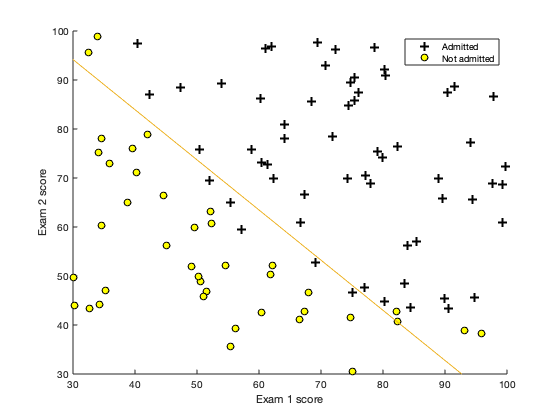


% Plot Boundary
plotDecisionBoundary(theta, X, y);
% Add some labels 
hold on;
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')
% Specified in plot order
legend('Admitted', 'Not admitted')
hold off;

# Regularized Logistic Regression 

### Loading the dataset

%  The first two columns contains the X values and the third column
%  contains the label (y).
dataset = load('ex2data2.txt');
X = dataset(:, [1, 2]); 
y = dataset(:, 3);

### Visualizing the data

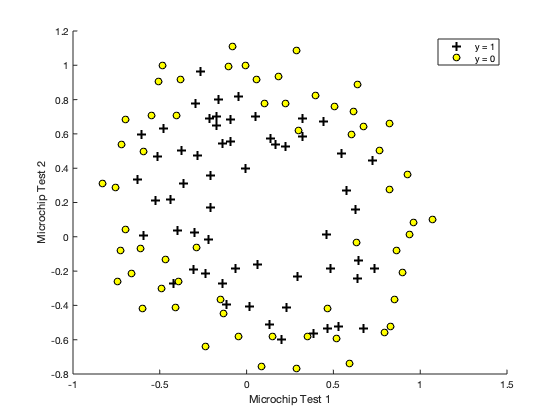

plotData(X, y);
% Put some labels 
hold on;
% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')
% Specified in plot order
legend('y = 1', 'y = 0')
hold off;

### Feature Mapping

% Add Polynomial Features
% Note that mapFeature also adds a column of ones for us, 
% so the intercept term is handled
X = mapFeature(X(:,1), X(:,2));

### Cost Function and gradient 

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

% Set regularization parameter lambda to 1
lambda = 1;

% Compute and display initial cost and gradient for regularized logistic regression
[cost, grad] = costFunctionReg(initial_theta, X, y, lambda);
fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

lambda = 1;
% Set Options
options = 
optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 1000);

% Optimize
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X, y, lambda)), ...


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


    initial_theta, options);

% Print theta
fprintf('Cost at theta found by fminunc: %f\n', cost);

Cost at theta found by fminunc: 0.693147



disp('theta:');disp(theta);

theta:
    1.2727
    0.6252
    1.1811
   -2.0200
   -0.9174
   -1.4316
    0.1240
   -0.3655
   -0.3572
   -0.1751
   -1.4582
   -0.0510
   -0.6156
   -0.2747
   -1.1928
   -0.2422
   -0.2060
   -0.0447
   -0.2778
   -0.2954
   -0.4564
   -1.0432
    0.0278
   -0.2924
    0.0156
   -0.3274
   -0.1439
   -0.9246



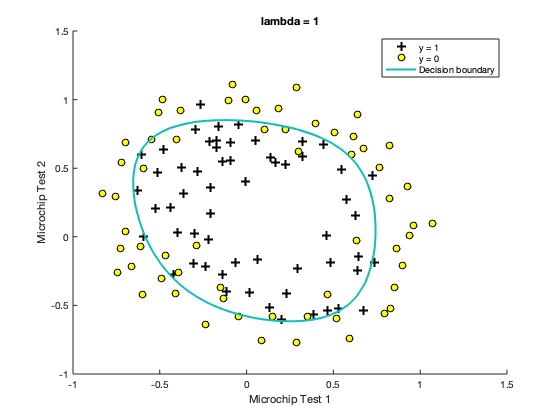

% Plot Boundary
plotDecisionBoundary(theta, X, y);
hold on;
title(sprintf('lambda = %g', lambda))

% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')

legend('y = 1', 'y = 0', 'Decision boundary')
hold off;


% Compute accuracy on our training set
p = predict(theta, X);

fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 83.050847
